clc; close all; clear all; warning off;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
B_start=70*1000;  %% MHz  暂定，低频段给探测，高频段给通信
Bandwidth=4*1000; %% totalbandwidth, MHz
Power_t=10^(0.1*12); %%  the total transmit power, 25 dBm
c=3*10^8;  %% light speed, m/s

N_chirp=100;  %% number of chirps
T_chirp= 40/10^6;  %% the duration time of a chirp, ms
G_st=40; g_st=10^(0.1*G_st); %% transmitter's antenna gain, in dB %% antenna gain
G_sr=25; g_sr=10^(0.1*G_sr); %% receiver's antenna gain, in dB %% antenna gain
rho_st=0.6;rho_sti=0.6;  %% radar cross section

L_gr=2;  %% path loss of gases and rain, in dB ,这个我已经在计算的时候进行单位换算了
L_ai=25;  %% additional loss and implementation loss, 20+5 dB
K_Boltzman=1.380649*10^(-23);  %% Boltzman's constant, m^2*kg*s^(-2)*K^(-1)
T_standard=290; %% temperature, K
F_n_s=10^(0.1*13);     %% noise figure in sensing, 10 dB

F_n_c=10^(0.1*10);     %% noise figure in sensing, 10 dB
G_cb=25;  g_cb= 10^(0.1*G_cb); %%  beamforming gain in communication in dB
C_diameter=10;  %% cover diameter, m

range_xy_BS=4000;range_xy_ST=4000;range_xy_SCT=4000;  %% simulation range, meter
d_tb_max=1000;d_bjt_max=1000;d_tit_max=1000;d_bti_max=1000;
r_bt_max=1000;r_bjt_max=1000;r_bjtj_max=1000;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% CP_(d_prime_s_res, tau_s, r_c_com, gamma_bs, gamma_st, eta, mu)
%%% CP_dd_tt_rr_ggb_ggt_ee_mm

d_prime_s_res_0=[0.05,0.1,0.15,0.2,0.25,0.3]; %% maximum distance resolution, m
tau_s_0        =[0.001,0.002,0.004,0.008,0.01];  %% threshold in sensing
r_c_com_0      =[0.1e9,0.2e9,0.3e9,0.4e9,0.5e9,0.6e9,0.7e9,0.8e9,0.9e9,1e9];  %% threshold/required data rate in communication, minimum communictaion data rate, 1Gbps

gamma_bs_0=[50:50:1000]./1000^2;  %%  density of base station, point/m^2
gamma_st_0=[300:50:2000]./1000^2;

eta_0=[0:0.02:1];  %% first \beta part of the spectrum is allocated to sensing
mu_0=[0:0.025:1];  %% first \mu part of the power is allocated to sensing
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


mu_int=zeros(1,1,size(mu_0,2)) ;
mu_int(1,1,:)=mu_0;
mu_000=repmat(mu_int, size(gamma_st_0,2), size(eta_0,2),1);        size(mu_000);

eta_int=zeros(1,size(eta_0,2),1);
eta_int(1,:,1)=eta_0;
eta_000=repmat(eta_int,size(gamma_st_0,2),1 ,size(mu_0,2));   size(eta_000);

gamma_st_int=zeros(size(gamma_st_0,2),1,1);
gamma_st_int(:,1,1)=gamma_st_0;
gamma_st_000= repmat(gamma_st_int,[1,size(eta_0,2),size(mu_0,2)]);    size(gamma_st_000);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


CP_s_dd_tt_rr_ggb_ggt_ee_mm_000_4=zeros(size(d_prime_s_res_0,2),size(tau_s_0,2),size(r_c_com_0,2),size(gamma_bs_0,2),...
    size(gamma_st_0,2),size(eta_0,2),size(mu_0,2));
CP_c_dd_tt_rr_ggb_ggt_ee_mm_000_4=zeros(size(d_prime_s_res_0,2),size(tau_s_0,2),size(r_c_com_0,2),size(gamma_bs_0,2),...
    size(gamma_st_0,2),size(eta_0,2),size(mu_0,2));

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


load('data/untiled_000_s_4_1.mat');
load('data/untiled_000_c_4_1.mat');
CP_s_dd_tt_rr_ggb_ggt_ee_mm_000_4(:,1,:,:,:,:,:)=CP_s_dd_tt_rr_ggb_ggt_ee_mm;
CP_c_dd_tt_rr_ggb_ggt_ee_mm_000_4(:,1,:,:,:,:,:)=CP_c_dd_tt_rr_ggb_ggt_ee_mm;

load('data/untiled_000_s_4_2.mat');
load('data/untiled_000_c_4_2.mat');
CP_s_dd_tt_rr_ggb_ggt_ee_mm_000_4(:,2,:,:,:,:,:)=CP_s_dd_tt_rr_ggb_ggt_ee_mm;
CP_c_dd_tt_rr_ggb_ggt_ee_mm_000_4(:,2,:,:,:,:,:)=CP_c_dd_tt_rr_ggb_ggt_ee_mm;

load('data/untiled_000_s_4_3.mat');
load('data/untiled_000_c_4_3.mat');
CP_s_dd_tt_rr_ggb_ggt_ee_mm_000_4(:,3,:,:,:,:,:)=CP_s_dd_tt_rr_ggb_ggt_ee_mm;
CP_c_dd_tt_rr_ggb_ggt_ee_mm_000_4(:,3,:,:,:,:,:)=CP_c_dd_tt_rr_ggb_ggt_ee_mm;

load('data/untiled_000_s_4_4.mat');
load('data/untiled_000_c_4_4.mat');
CP_s_dd_tt_rr_ggb_ggt_ee_mm_000_4(:,4,:,:,:,:,:)=CP_s_dd_tt_rr_ggb_ggt_ee_mm;
CP_c_dd_tt_rr_ggb_ggt_ee_mm_000_4(:,4,:,:,:,:,:)=CP_c_dd_tt_rr_ggb_ggt_ee_mm;

load('data/untiled_000_s_4_5.mat');
load('data/untiled_000_c_4_5.mat');
CP_s_dd_tt_rr_ggb_ggt_ee_mm_000_4(:,5,:,:,:,:,:)=CP_s_dd_tt_rr_ggb_ggt_ee_mm;
CP_c_dd_tt_rr_ggb_ggt_ee_mm_000_4(:,5,:,:,:,:,:)=CP_c_dd_tt_rr_ggb_ggt_ee_mm;



size(CP_s_dd_tt_rr_ggb_ggt_ee_mm_000_4);






joint_CP_dd_tt_rr_ggb_ggt_ee_mm=CP_s_dd_tt_rr_ggb_ggt_ee_mm_000_4.*CP_c_dd_tt_rr_ggb_ggt_ee_mm_000_4;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


max_CP_dd_tt_rr_ggb_ggt=zeros(size(d_prime_s_res_0,2),size(tau_s_0,2),size(r_c_com_0,2),size(gamma_bs_0,2),size(gamma_st_0,2));

for dd=1:size(d_prime_s_res_0,2)
    for tt=1:size(tau_s_0,2)
        for rr=1:size(r_c_com_0,2)
            for ggb=1:1:size(gamma_bs_0,2)
                
                for ggt=1:1:size(gamma_st_0,2)
                    
                    [y_ggt,x_ggb]=meshgrid(mu_0,eta_0);
                    
                    joint_CP_dd_tt_rr_ggb_ggr=zeros(size(eta_0,2),size(mu_0,2));
                    joint_CP_dd_tt_rr_ggb_ggr(:,:)=joint_CP_dd_tt_rr_ggb_ggt_ee_mm(dd,tt,rr,ggb,ggt,:,:);
                    
                    max_value_eta_mu=max(max(joint_CP_dd_tt_rr_ggb_ggr));
                    [max_eta_index,max_mu_index]=find(max_value_eta_mu==joint_CP_dd_tt_rr_ggb_ggr);
                    max_eta_mu=[eta_0(1,max_eta_index),mu_0(1,max_mu_index)];
                    
                    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                    max_CP_dd_tt_rr_ggb_ggt(dd,tt,rr,ggb,ggt)=max_value_eta_mu;
                end
            end
        end
    end
end

% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

dd_tt_rr_loss=zeros(size(d_prime_s_res_0,2),size(tau_s_0,2),size(r_c_com_0,2));


num=0;
for dd=1:size(d_prime_s_res_0,2)
    for tt=1:size(tau_s_0,2)
        for rr=1:size(r_c_com_0,2)
            num=num+1;
            
            d_prime_s_res=d_prime_s_res_0(1,dd);
            tau_s=tau_s_0 (1,tt);
            r_c_com=r_c_com_0(1,rr);
            
            [y_ggt,x_ggb]=meshgrid(gamma_st_0,gamma_bs_0);
            
            max_joint_CP_dd_tt_rr=zeros(size(gamma_bs_0,2),size(gamma_st_0,2));
            max_joint_CP_dd_tt_rr(:,:)=max_CP_dd_tt_rr_ggb_ggt(dd,tt,rr,:,:);
            
            max_value_ggb_ggt=max(max(max_joint_CP_dd_tt_rr));
            
            
            dd_tt_rr_loss(dd,tt,rr)=max_value_ggb_ggt;
            
            
        end
    end
end


size(dd_tt_rr_loss)

ans =      6     5    10


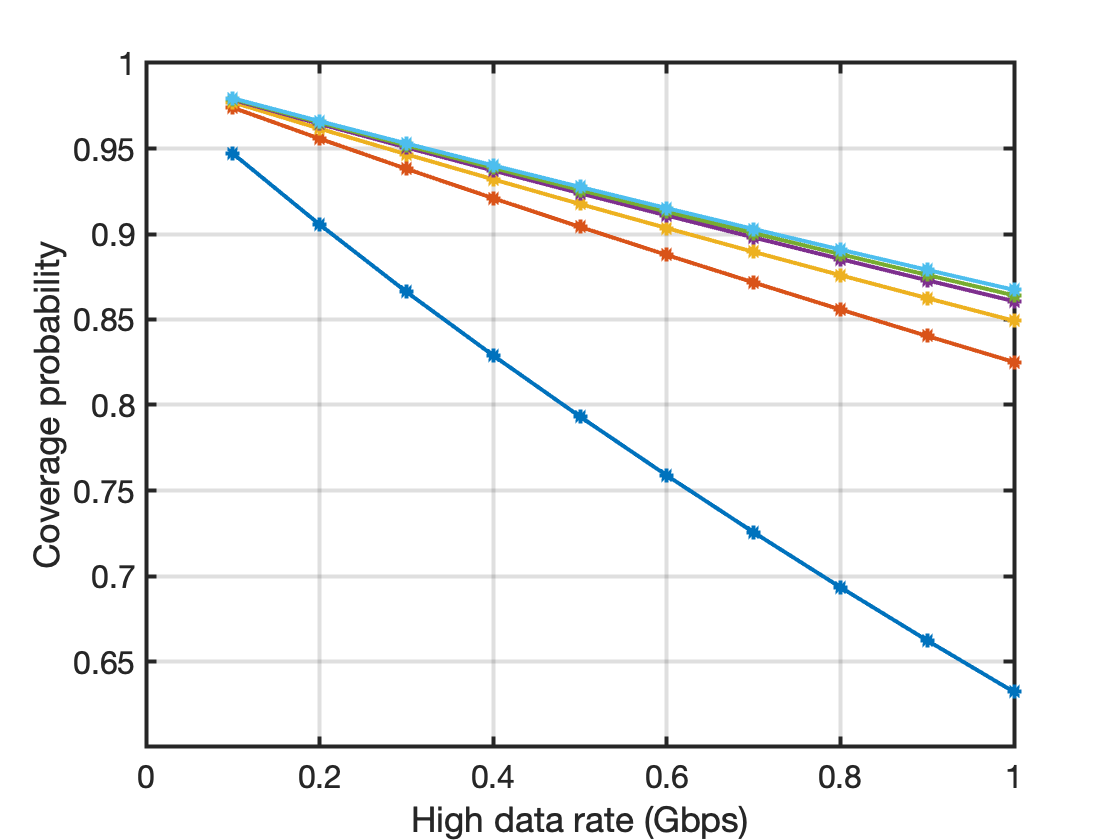



figure()
rr=zeros(1,size(r_c_com_0 ,2));

for ddd=1:size(d_prime_s_res_0,2)
    rr(1,:)= dd_tt_rr_loss(ddd,1,:);
    plot(r_c_com_0/1e9,rr,'-*','LineWidth',2);hold on;
    
%     x1=r_c_com_0(1,4:6);
% y1=rr(1,4:6);
%     
%     axes('Position',[0.2e9,0.4e9,0.7,0.8]); % 生成子图
% plot(x1,y1); % 绘制局部曲线图
    
end

xlabel('High data rate (Gbps)' );
ylabel('Coverage probability' );


set(gca,'LineWidth',2,'FontSize',16);
grid on;



hold off;

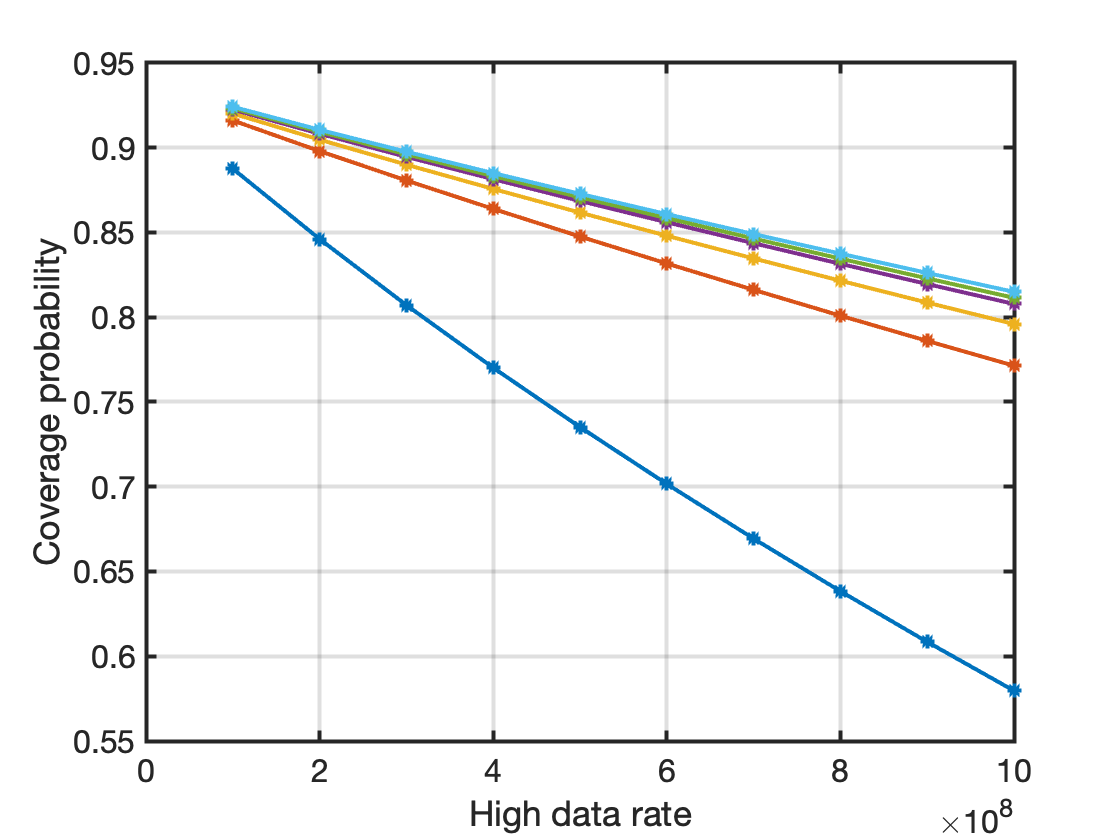






%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure()
rr=zeros(1,size(r_c_com_0 ,2));
for ddd=1:size(d_prime_s_res_0,2)
    rr(1,:)= dd_tt_rr_loss(ddd,5,:);
    plot(r_c_com_0,rr,'-*','LineWidth',2);hold on;
end

xlabel('High data rate' );
ylabel('Coverage probability' );

set(gca,'LineWidth',2,'FontSize',16);
grid on;